clc,clear
% PLEASE READ ALL THE LOCKED COMMENTS CAREFULLY BEFORE SUBMITTING ANY ANSWERS. 
% IF YOU DO NOT READ THESE COMMENTS, YOU ARE LIKELY TO OVERLOOK AN IMPORTANT DETAIL 
% OF THE REQUIRED SUBMISSION STYLE.

% Import your data and make any preliminary calculations between here and the next
% set of locked lines.
RawData_Air = readtable('Raw_Data.xlsx','sheet','Air')

RawData_Air = 21×18 table
    Temperature_degC_    V0_20L    V0_25L    V0_30L    V0_35L    V0_40L    V0_45L     V0_50L     V0_55L     V0_60L     V0_65L     V0_70L     V0_75L     V0_80L     V0_85L     V0_90L     V0_95L      V1_0L 
    _________________    ______    ______    ______    ______    ______    ______    ________    _______    _______    _______    _______    _______    _______    _______    _______    

RawData_CO2 = readtable('Raw_Data.xlsx','sheet','CO2')

RawData_CO2 = 21×16 table
    Temperature_degC_     V0_30L     V0_35L     V0_40L     V0_45L     V0_50L     V0_55L     V0_60L     V0_65L     V0_70L     V0_75L     V0_80L     V0_85L     V0_90L     V0_95L      V1_0L 
    _________________    ________    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______

           40             -2.4262     -15.93    -29.0

RawData_N2 = readtable('Raw_Data.xlsx','sheet','N2')

RawData_N2 = 21×20 table
    Temperature_degC_    V0_1L     V0_15L    V0_20L    V0_25L    V0_30L    V0_35L    V0_40L    V0_45L    V0_50L     V0_55L     V0_60L     V0_65L     V0_70L     V0_75L     V0_80L     V0_85L     V0_90L     V0_95L      V1_0L 
    _________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ________    _______    _______    _______    ______

% Create your Boyle's Law plot between here and the next set of locked lines.
F1 = figure(1) % create a figure handle called F1, for checking your answers

F1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


% make sure your figure has a legend or MATLAB Grader will not grade your work correctly.
RawDataAir = RawData_Air(:, 2:end);
APressure = 102; %in kPa
Boyle50 = RawDataAir(6,:)+APressure;
Boyle60 = RawDataAir(11,:)+APressure;
Boyle70 = RawDataAir(16,:)+APressure;
%table to aray
tBoyle50=table2array(Boyle50)

tBoyle50 =   237.5825  198.9572  164.3689  137.7695  124.2944  110.6218   99.3460   90.4749   82.6688   76.9838   69.9707   67.3713   61.2225   60.0543   51.9004   53.8961   54.8427


tBoyle60=table2array(Boyle60)

tBoyle60 =   261.9655  198.8545  172.1948  149.2452  128.6934  113.4884  102.3556   93.4252   85.7997   80.7887   72.7469   65.6472   64.6404   60.7529   56.7049   55.3152   48.6453


tBoyle70=table2array(Boyle70)

tBoyle70 =   269.7261  209.9154  176.2455  154.9043  131.2563  116.8436  105.1898   95.9117   88.1862   82.5082   76.0370   68.6567   64.6788   62.5289   60.3026   55.9112   54.8797


%xvector creation
VAT = ( .2 : .05 : 1 ) *1e-3

VAT = 1.0e-03 *

    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


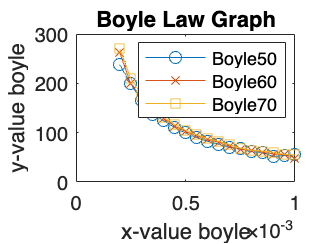

%plotting
plot(VAT,tBoyle50,'-o')
hold on %keeps current plot
plot(VAT,tBoyle60,'-x')
plot(VAT,tBoyle70,'-s')
hold off
xlabel('x-value boyle')
ylabel('y-value boyle')
title('Boyle Law Graph')
legend('Boyle50','Boyle60','Boyle70');

% Plot your Gay-Lussac's Law figure between here and the next set of locked lines.
F2 = figure(2) % create a figure handle called F2, for checking your answers

F2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


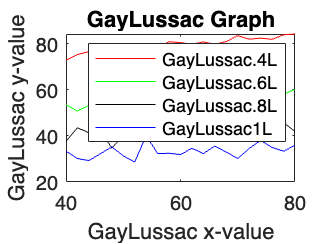

% make sure your figure has a legend or MATLAB Grader will not grade your work correctly.
RawDataCO2 = RawData_CO2(:, 2:end);
GayLussac4 = table2array(RawDataCO2(:,3)+APressure);
GayLussac6 = table2array(RawDataCO2(:,7)+APressure);
GayLussac8 = table2array(RawDataCO2(:,11)+APressure);
GayLussac10 = table2array(RawDataCO2(:,15)+APressure);
%temp Vector creation
TCO2 = (40:2:80);
%plotting
plot(TCO2,GayLussac4,'r-')
hold on
plot(TCO2,GayLussac6,'g-')
plot(TCO2,GayLussac8,'k-')
plot(TCO2,GayLussac10,'b-')
hold off
xlabel('GayLussac x-value')
ylabel('GayLussac y-value')
title('GayLussac Graph')
legend('GayLussac.4L','GayLussac.6L','GayLussac.8L','GayLussac1L')

% Perform the rest of your calculations below this locked line.
%establish pressure
Pair = table2array(RawData_Air(:,2:end))+APressure;
Pco2 = table2array(RawData_CO2(:,2:end))+APressure;
Pn2 = table2array(RawData_N2(:,2:end))+APressure;
%establish Volumes
Vair = (.2 : .05 :1)*1e-3;
Vco2 = (.3 : .05 :1)*1e-3;
Vn2 = (.1 : .05 :1)*1e-3;
%establish Mass
Mair = 525e-6;
Mco2 = 495e-6;
Mn2 = 575e-6;
%establish temp
Tair = table2array(RawData_Air(:,1)) + 273;
Tco2 = table2array(RawData_Air(:,1)) + 273;
Tn2 = table2array(RawData_Air(:,1)) + 273;
%gas const
Rair = mean(mean((Pair .* Vair)./(Tair .* Mair)));
Rco2 = mean(mean((Pco2 .* Vco2)./(Tco2 .* Mco2)));
Rn2 = mean(mean((Pn2 .* Vn2)./(Tn2 .* Mn2)));
%percent diff
diffRair=(abs((287.0e-3 -Rair)/(287.0e-3))*100); %abs mass-const/mass
diffRCO2=(abs((188.9e-3-Rco2)/(188.9e-3))*100);
diffRN2=(abs((296.8e-3 -Rn2)/(296.8e-3))*100);
%uncertinity
uRair=1.96*std2((Pair .* Vair)./(Tair .* Mair)) / sqrt(17*21);
uRco2=1.96*std2((Pco2 .* Vco2)./(Tco2 .* Mco2)) / sqrt(15*21);
uRn2=1.96*std2((Pn2 .* Vn2)./(Tn2 .* Mn2)) / sqrt(19*21);
%calculation ru
uair= Rair*28.97;
uco2=Rco2*44.01;
uN2=Rn2*28.013;
%avg (wieghted)
Ru=(uair*(17*21)+uco2*(15*21)+uN2*(19*21))/(17*21+21*15+21*19);
% %diff
diffRu=abs(((8.314-Ru)/Ru)*100);
% uncertinity
Table=[((Pair .* Vair) ./ (Tair .* Mair) .* 28.97) ((Pco2 .* Vco2) ./ (Tco2 .* Mco2) .* 44.01) ((Pn2 .* Vn2) ./ (Tn2 .* Mn2) .* 28.013)];
uRu=1.96*std2(Table)/sqrt(51*21);